# 真值说明文档

#### 真值测试，函数：predict_resilience.m

#### 测试数据集：Res_0815.mat

clear all
load Res_0815.mat
%ind = 42;
%casename = Res{ind,1}
%mpc = Res{ind,4}.mpc;
%Real_Resi = Res{ind,4}.load;
%Real_posi_Pmax = Res{ind,4}.gen;

# 预测真值并比较结果sample

#### 函数输入：Load_Direction (n * 2 double), Real_posi_Pmax (n * 2 double), Real_Resi(n*2 double)

#### 函数输出：res (1 * 1 structure)

函数说明 : 

- （注释）默认扰动所有P>0且Q>0节点。

- （可选）输入Load_Direction，弹性sample，消耗纯P，direction = 1。

- （可选）输入Real_posi_Pmax，则输出仅包含直接预测与减初始负载。

- （可选）输入Real_Resi，则输出包含与真值比较结果。

- （注释）弹性情况不考虑初始负载大小，输入Load_direction则会考虑。

%ind = 54;
%casename = Res{ind,1}
%mpc = Res{ind,4}.mpc;
%Real_Resi = Res{ind,4}.load;
%Real_posi_Pmax = Res{ind,4}.gen;
%res = predict_resilience(mpc,'Real_Resi',Real_Resi,...
%    'Real_Pmax',Real_posi_Pmax);
%runtime_second = vpa(res.runtime_second,4)

# 批量测试并输出误差

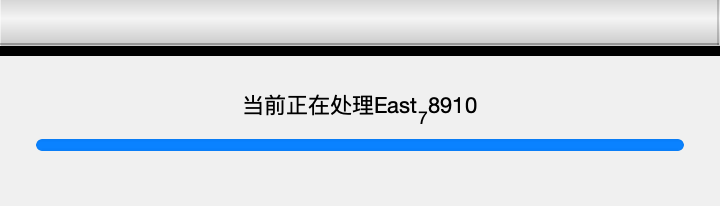

错误使用 full
请求的 75344x75344 (84.6GB)数组超过预设的最大数组大小(64.0GB)。这可能会导致 MATLAB 无响应。

出错 predict_resilience>Father_matrix (第 155 行)
B = (full(Y(load_index,load_index)))^(-1);

出错 predict_resilience (第 59 行)
[weight,Y_eq]= Father_matrix(Y,g_index,p_

ind_set = [1:78];
bar = waitbar(0,'进度条');
for loop = 1 : numel(ind_set)
    ind = ind_set(loop);
    casename = Res{ind,1};
    waitbar(loop/numel(ind_set),bar,['当前正在处理',casename]) 
    mpc = Res{ind,4}.mpc;
    Real_Resi = Res{ind,4}.load;
    Real_posi_Pmax = Res{ind,4}.gen;
    res = predict_resilience(mpc,'Real_Resi',Real_Resi,...
        'Real_Pmax',Real_posi_Pmax);
    R{ind,1} = casename;
    R{ind,2} = res;
    R{ind,3} = res.result.ave1;
    R{ind,4} = res.result.med1;
    R{ind,5} = res.result.ave2;
    R{ind,6} = res.result.med2;
    R{ind,7} = res.result.ave3;
    R{ind,8} = res.result.med3;
    save('resi_result_0907.mat','R');
end

close(bar)


# 表格内容输出

load resi_result_0905.mat
ind_set = [70,76,46,54,42,...
    47,49,53,74,77,...
    5,9,20,31,39,50,57,62,65,66,73,75];
table = [];
for loop = 1 : numel(ind_set)
    ind = ind_set(loop);
    mpc = Res{ind,4}.mpc;
    lam = R{ind,2}.lambda_set;
    table{loop,1} = Res{ind,1};
    table{loop,2} = numel(mpc.bus(:,1));
    table{loop,3} = numel(mpc.branch(:,1));
    table{loop,4} = numel(Res{ind,4}.gen(:,1));
    table{loop,5} = numel(Res{ind,4}.load(:,1));
    table{loop,6} = round(mean(lam(:,2) ./ lam(:,1)),2);
    table{loop,7} = round(mean(R{ind,2}.c2),2);
    table{loop,8} = round(R{ind,2}.result.ave3,1);
    table{loop,9} = round(R{ind,2}.result.med3,1);
end
save('table_result_0907.mat','table')